# splWindows

A script to calculate a lobing pattern of tonal and broadband sound pressure level measurements at an array of hydrophones from a passing ship using its AIS track. By grouping all of the consecutive measurements along the ships track by same look angle (azimuth), the lobing characteristics of the ship's noise signature can be estimated. 

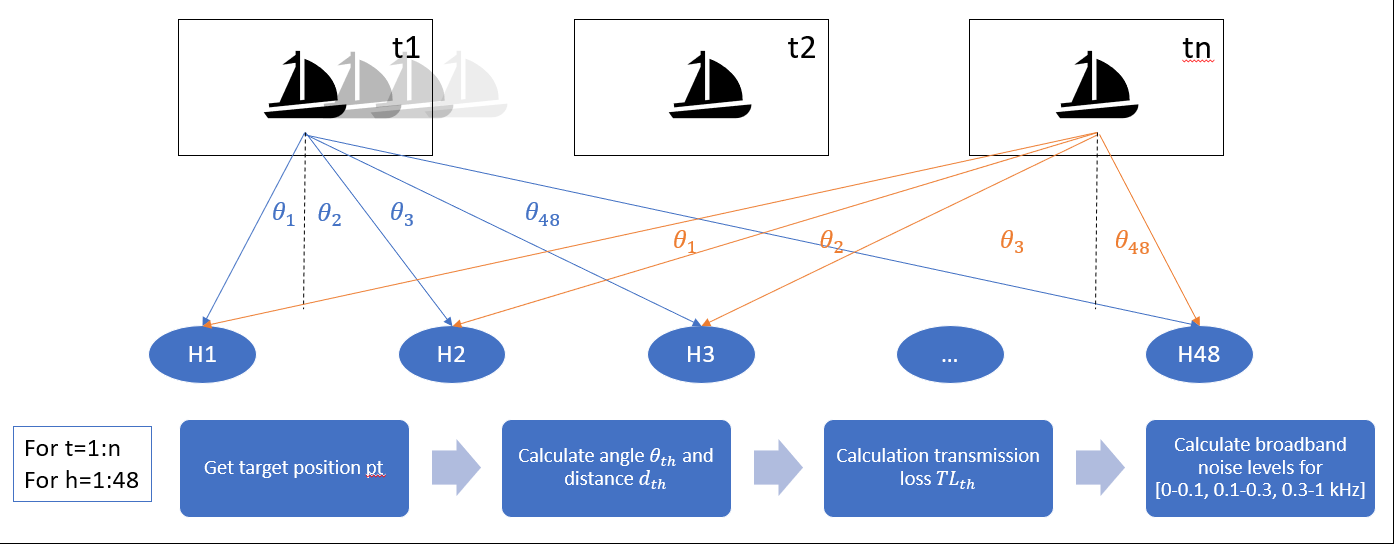

## Initialize

clearvars

#### Flip switches

VOI = 'OcEnd-AAA1-30Aug';
AOI = 'AAA1';
sampling = 'full';
plotSpectrogram = 'yes';
plotSpectra = 'yes';
plotShipTrack = 'yes';
plotBearingHistory = 'yes';
plotSpatialSummary = 'yes';
plotIntTrack = 'no';
plotAspects = 'yes';

#### Set parameters

Num1secSeg = 5;                             %number of segments for averaging
TimeIntSec = 3;                             %time-difference [sec] btw. beginning of segments
fstartind = 10;                             %10Hz for computing received levels
fstopind = 1001;                            %1000Hz for computing received levels
NumRec = 48;                                %number of hydrophone channels
BinWidth = 1;                               %processing bin width [Hz]
RefRecInd = 24;                             %reference hydrophone for spatial center
nArrays = 2;                                %number of hydrophone arrays
ref.Array = 1;                              %reference array (AAA1 or AAA2)
par.km2m = 1000;                            %convert km to m
par.km2kts = 1.9434;                        %convert km to kts
par.spread = 10;                            %spreading coefficient
par.scale = 10;                             %min for polarscatter (dB)
par.bbLim = [170 200];                      %range for broadband polarscatter
par.nbLim = [140 195];                      %range for narrowband polarscatter
par.scatInt = 1;                            %every nth hph element is included in polar scatterplot
par.fontSize = 14;                          %font size for plots

## Acoustic data pre-processing

### Define parameters

sens = 194.5;                   % (nominal) dB re 1V/uPa
cal = 10^(sens/20);             % hydrophone calibration
gain.amp = 0;%-70;                 % Amplifier gain 70 dB (adjustable), A/D -8 dB (I don't think gain is correct - confirm A/D)
gain.adc = 0; %20*log(5/(2^16));    % 1 Vrms = 16 bit peak-to-peak --> could also be +/- 1 floating point range (20log(2.0/5.0))
gain.fft = 0;                   % FFT gain is applied in spectra (2/NFFT)

### Load acoustic data

dFile = 'allCh.wav';           % Select the 48-ch (allCh) or 1-ch (singleCh) file
switch VOI
    case 'OcEnd-AAA1-30Aug'
        NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150830_AAA1\proc',dFile);
        startTime = datetime(2015,8,30,9,31,16);  % east_aaa1_20150830_093116_00_0000
    case 'OcEnd-AAA2-30Aug'
        NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150830_AAA2\proc',dFile);
        startTime = datetime(2015,8,30,9,26,43);  % west_aaa2_20150830_092643_00_0008
    case 'OcEnd-AAA1-31Aug'
        NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150831_AAA1\proc',dFile);
        startTime = datetime(2015,8,31,17,59,29); % east_aaa1_20150831_175929_00_0001
    case 'OcEnd-AAA2-31Aug'
        NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150831_AAA2\proc',dFile);
        startTime = datetime(2015,8,31,17,56,55); % west_aaa2_20150831_175655_00_0006
end
[x,fs] = audioread(NWFile);  % What is this signal? Volts? --> need to convert to dB (x/sens)
SegLengthSamples = BinWidth*fs;
DataLengthSamples = Num1secSeg*SegLengthSamples;

### Downsample acoustic data (optional)

switch sampling
    case 'full'
        nFactor = 1;
        disp('sampling full band')
    case 'downsample'
        nFactor = 1000;
        y = downsample(x,nFactor); %downsample or decimate?
        x = y;
        clear y
end

sampling full band


[nsam,nch] = size(x);

### Generate time vector

StartTime = datenum(startTime);
endTime = startTime + seconds(length(x(:,1))/fs);
EndTime = datenum(endTime);
TimeVector = StartTime:TimeIntSec/(3600*24):EndTime;
NumSpec = length(TimeVector);

### Correct for A/D and pre-amp gain

gain.total = 10^((gain.amp+gain.adc+gain.fft)/10);    %substitute for G at some point
gain.step = 2;

### Transfer function for array

One-sided to save memory

fRspectra = fs/2*linspace(0,1,SegLengthSamples/2+1);    %frequencies [Hz]
G = 10^(sens/20);                                       %Array transfer function is flat across frequencies

## Received spectra with 1 Hz bins

Each of the 48 pressure time series is divided into consecutive, non-overlapping segments with a length of 1 s.

S =  cell(NumRec,1);   % Spectra for each array elements
for RecInd=1:NumRec
    S{RecInd} = zeros(NumSpec-2,SegLengthSamples/2+1);  % 48 x fs  (one-sided)
end

### Loop to read data piece by piece

for EventIndex = 1:(NumSpec-2)
    for RecInd=1:NumRec
        data = x(TimeIntSec*fs*(EventIndex-1)+1:...
            TimeIntSec*fs*(EventIndex-1)+DataLengthSamples,RecInd);
        NumSeg = floor(length(data)/SegLengthSamples);

### Compute received spectra

Apply a two-sided FFT to each segment to yield a frequency bin spacing of 1 Hz. The magnitude squared values of the complex FFT coefficients for the positive frequencies were multiplied by 2/NFFT^2 to account for the processing gain of the FFT.

        X = fft(reshape(data(1:NumSeg*SegLengthSamples),...
            SegLengthSamples,NumSeg));
        S{RecInd}(EventIndex,:) = ...
            (sum(2*abs(X(1:SegLengthSamples/2+1,:)).^2,2)*G^2)...
            /(NumSeg*SegLengthSamples*fs);
    end
    

#### Display progress

    if mod(EventIndex,round(NumSpec/10))==0
        disp([num2str(round(100*EventIndex/NumSpec)) '% done'])
    end
end

10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done


### Correct for changes in gain

if strcmp(VOI,'OcEnd-AAA1-30Aug')
    [gainStart,gainEnd] = unGain(x,SegLengthSamples,TimeIntSec)
    for RecInd=1:NumRec
        S{RecInd}(gainStart:gainEnd,:) = ...
            S{RecInd}(gainStart:gainEnd,:)*gain.step^2;
    end
end

gainStart = 177

gainEnd = 435

### Plot spectrograms

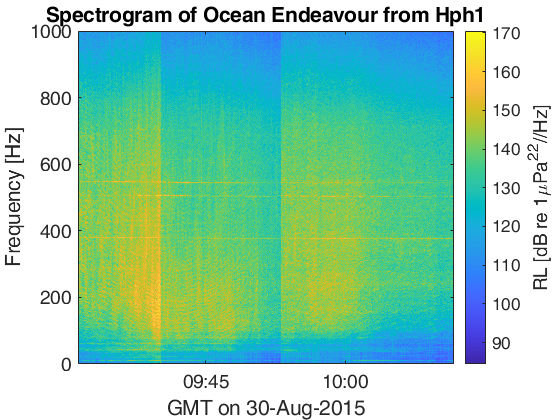

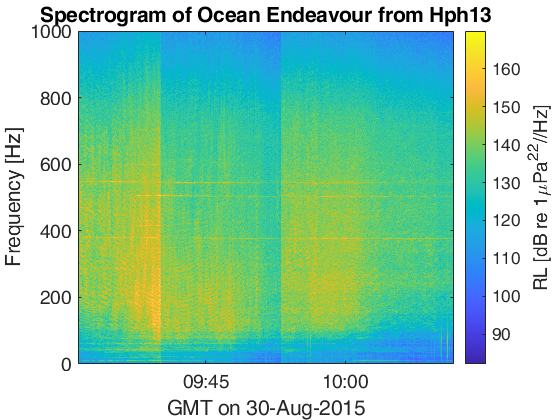

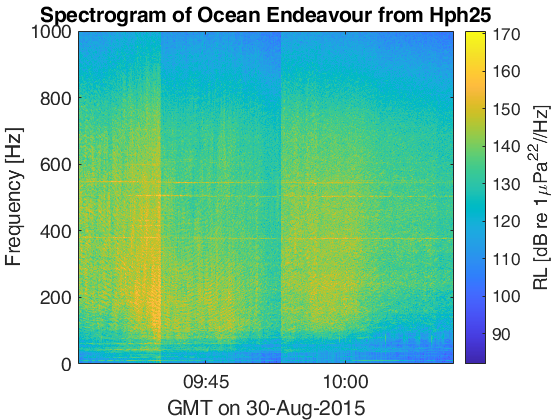

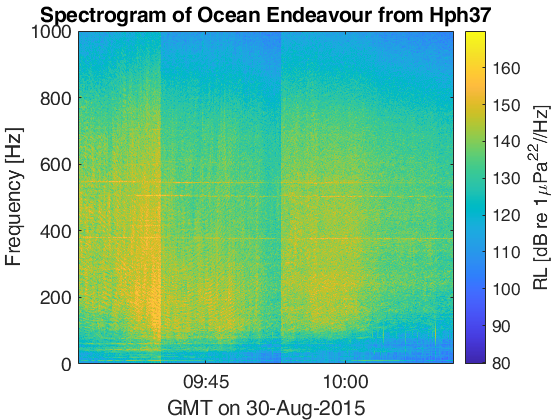

switch plotSpectrogram
    case 'no'
    case 'yes'
           for RecInd=1:12:NumRec
            figure;
            %RecInd = RefRecInd;
            imagesc(TimeVector,fRspectra,10*log10(S{RecInd}).');
            title(['Spectrogram of Ocean Endeavour from Hph' num2str(RecInd)],'FontSize',par.fontSize)
            axis xy;
            h = colorbar;%caxis([50 130])
            set(get(h,'ylabel'),'string','RL [dB re 1\muPa^2^2//Hz]',...
                'FontSize',par.fontSize);
            datetick('x','keeplimits');
            xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')],...
                'FontSize',par.fontSize)
            ylabel('Frequency [Hz]','FontSize',par.fontSize)
            ylim([0 1000])
            set(gca, 'FontSize',par.fontSize)
        end
end

## Plot average spectra

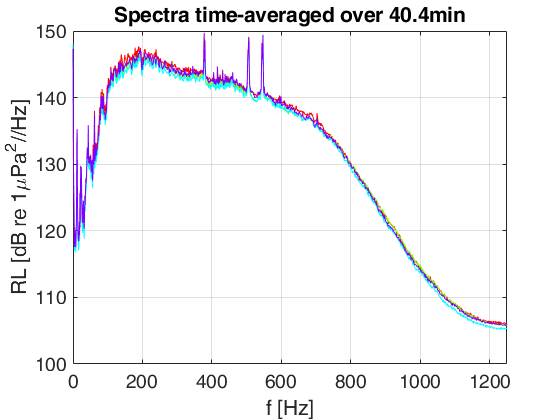

switch plotSpectra
    case 'no'
    case 'yes'
        figure
        colorarray = hsv(NumRec);
        for RecInd=1:12:NumRec
            plot(fRspectra,10*log10(sum(S{RecInd})/NumSpec),...
                'Color',colorarray(RecInd,:));
            hold on                     
        end
        grid on
        title(['Spectra time-averaged over '...
                    num2str((TimeVector(end)-TimeVector(1))*24*60) 'min'],'FontSize',par.fontSize)
        ylabel('RL [dB re 1\muPa^2//Hz]','FontSize',par.fontSize)
        xlabel('f [Hz]','FontSize',par.fontSize)
        set(gca, 'FontSize',par.fontSize)
        %ylim([60 130])
        xlim([0 1250])
end

## Compute received levels

The squared received sound pressures for each hph are reported on a relative logarithmic scale in dB with a reference pressure of 1 uPa^2 and are referred to as received levels (RLs)

RLship = zeros(NumRec,NumSpec-2);       %broad band received level [dB]

for RecInd = 1:NumRec
    for index=1:NumSpec-2
        %compute source level from spectrum for beam angle
        RLship(RecInd,index) = 10*log10(trapz(fRspectra(fstartind:fstopind),...
            (S{RecInd}(index,fstartind:fstopind))));%...
    end
end
RLship = (RLship+gain.total)';

## Spatial data processing

#### Load array locations

load arrays_lat-long
% array1=table2array(array1(:,1:3));
% array2=table2array(array2(:,1:3));
A{1}=table2cell(array1);
A{2}=table2cell(array2);

### Load AIS file

Load - sync to spec - calc TL - calc SL - 

m = matfile('byShip.mat');
AIS = m.Oc_End; %m.Heb_Sky;
AIS = sortrows(AIS,'datetime','ascend');
mmsi = AIS.mmsi(1);
AIS.mmsi = []; AIS.rate_of_turn = []; AIS.hdg = [];  % eliminate unused vars
AIStime = table2timetable(AIS);  % might need to make all of this a structure
AIStimeRange = timerange((startTime),(endTime-seconds(6)));  %because integration periods
AIStime = AIStime(AIStimeRange,:);

### Synchronize spectral and spatial data

Make RL and TL same length and combine in time 

timeVector = datetime(TimeVector(1:length(S{1}(:,1))),'ConvertFrom','datenum')';
RLtime = timetable(timeVector,RLship);
SPL = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(3)); %'KeepOriginalTimes',true
SPL = SPL(1:height(RLtime),:); %[RLsync,AISsync] = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(30));

### Calculate ranges along ship track

% [R1,R2] = calcDist(SPL.lat, SPL.long, array1(:,1:2), array2(:,1:2));
% SPL = addvars(SPL,R1,R2);
[R1,R2] = calcDist(SPL.lat, SPL.long, [array1.lat array1.long], [array2.lat array2.long]);
SPL = addvars(SPL,R1,R2);

### Calculate CPA range and time

[rangeCPA_1,timeCPA_1] = min(R1(:,1,1));
[rangeCPA_2,timeCPA_2] = min(R2(:,1,1));
specCPA = 'CPA range AAA1 = %4.2f km and AAA2 = %4.2f km';
fprintf(specCPA,rangeCPA_1,rangeCPA_2);

CPA range AAA1 = 2.04 km and AAA2 = 1.33 km

### Plot ship track vs array

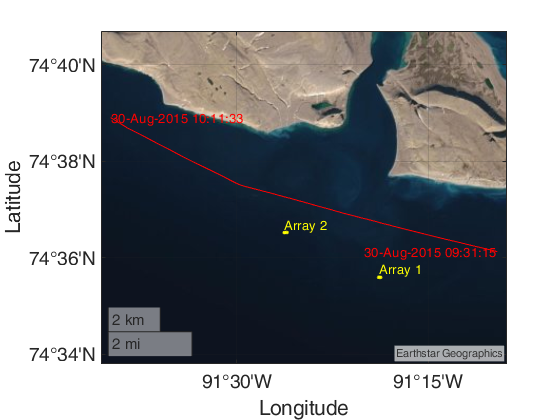

switch plotShipTrack
    case 'no'
    case 'yes'
        figure
        geoplot([SPL.lat], [SPL.long],'r-',...
            [array2.lat],[array2.long],'y.',...
            [array1.lat],[array1.long],'y.')
        text(SPL.lat(1),SPL.long(1),datestr(SPL.timeVector(1)),...
            'HorizontalAlignment','right',"Color",'r');
        text(SPL.lat(end),SPL.long(end),datestr(SPL.timeVector(end)),...
            'HorizontalAlignment','left',"Color",'r');
        text(array1.lat(1),array1.long(1),'Array 1',...
            'VerticalAlignment','bottom',"Color",'y');
        text(array2.lat(1),array2.long(1),'Array 2',...
            'VerticalAlignment','bottom',"Color",'y');
        set(gca, 'FontSize',par.fontSize)
        %geobasemap colorterrain
        %[SPL.lat], [SPL.long],'b*',...
        geobasemap satellite
end

### Plot bearing histogram of ranges

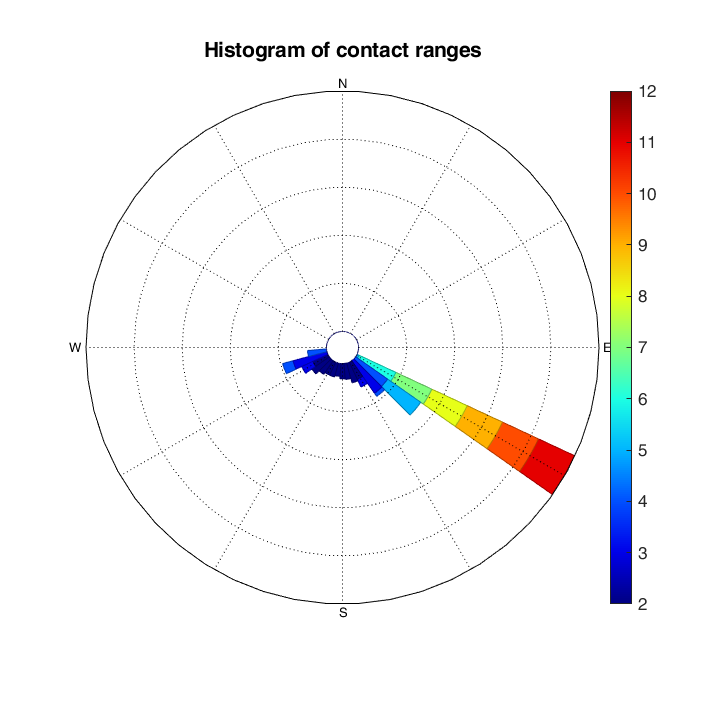

switch plotBearingHistory
    case 'no'
    case 'yes'
        rangeRoser(R1(:,1,2), R1(:,1,1), 'legendtype', 1, 'anglenorth', 0, 'angleeast', 90, 'lablegend', 'Distance (km)');
        set(gca,'FontSize',14);
end

#### Determine look angle (aspect)

SPL.aspect2 = SPL.crs - SPL.R2(:,:,2);
SPL.rads2 = deg2rad(SPL.aspect2);
SPL.aspect1 = SPL.crs - SPL.R1(:,:,2);
SPL.rads1 = deg2rad(SPL.aspect1);
switch AOI
    case 'AAA1'
        SPL.rads = SPL.rads1;
    case 'AAA2'
        SPL.rads = SPL.rads2;
end

### Plot ship aspects over track

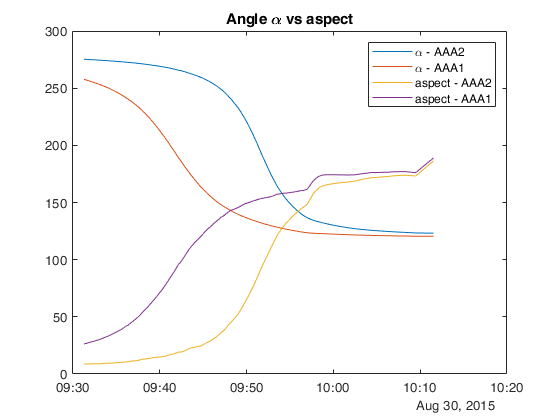

switch plotAspects
    case 'no'
    case 'yes'
        figure
        plot(SPL.timeVector,SPL.R2(:,RefRecInd,2))
        hold on
        plot(SPL.timeVector,SPL.R1(:,RefRecInd,2))
        plot(SPL.timeVector,SPL.aspect2(:,RefRecInd))
        plot(SPL.timeVector,SPL.aspect1(:,RefRecInd))
        title({'Angle \alpha vs aspect'})
        legend('\alpha - AAA2','\alpha - AAA1','aspect - AAA2','aspect - AAA1')
end

### Plot time resolution of AIS data, speed and range history of contact

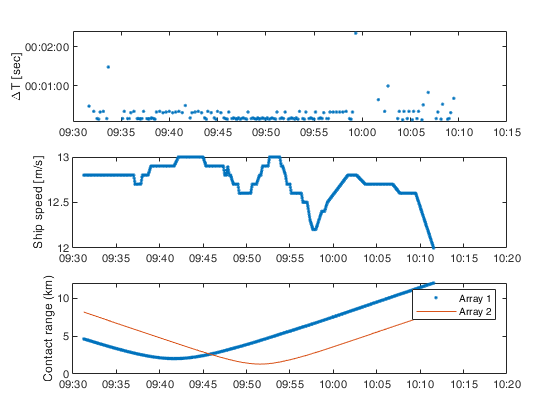

switch plotSpatialSummary
    case 'no'
    case 'yes'
        figure
        subplot(3,1,1)
        plot(AIStime.datetime(1:end-1),diff(AIStime.datetime),'.');
        datetick('x')
        ylabel('\DeltaT [sec]')
        subplot(3,1,2)
        plot(SPL.timeVector,SPL.speed_over_ground,'.');
        datetick('x')
        ylabel('Ship speed [m/s]')
        subplot(3,1,3)
        plot(SPL.timeVector,R1(:,RefRecInd,1),'.');
        hold on
        plot(SPL.timeVector,R2(:,RefRecInd,1),'-')
        datetick('x')
        ylabel('Contact range (km)')
        legend('Array 1','Array 2')
end

### Transform AIS lats/longs to x-y   

SPL.vx = zeros(height(SPL),1);
SPL.vy = zeros(height(SPL),1);
SPL.v = zeros(height(SPL),1);

[SPL.x, SPL.y] = latlon2xy(SPL.lat,SPL.long,...
    array2.lat(RefRecInd),array2.long(RefRecInd));

[array1.x, array1.y] = latlon2xy(array1.lat(:),array1.long(:),...
    array2.lat(RefRecInd),array2.long(RefRecInd));
[array2.x, array2.y] = latlon2xy(array2.lat(:),array2.long(:),...
    array2.lat(RefRecInd),array2.long(RefRecInd));
arrays = [array1.x array1.y -1/par.km2m*array1.depth];
arrays(:,:,2) = [array2.x array2.y -1/par.km2m*array2.depth];  %negative depth

### Calculate x and y components of ship speed

SPL.vx(1:end-1) = diff(SPL.x)./(diff(datenum(SPL.timeVector)*24*3600)); %km/s
SPL.vx(end) = SPL.vx(end-1);
SPL.vy(1:end-1) = diff(SPL.y)./(diff(datenum(SPL.timeVector)*24*3600)); %km/s
SPL.vx(end) = SPL.vx(end-1);
SPL.v = sqrt(SPL.vx.^2 + SPL.vy.^2); %km/s


### Plot Interpolated Track

funPlotIntTrack(SPL, par, TimeVector, plotIntTrack);

### Compute radiation pattern

alpha = zeros(NumRec,NumSpec-2,nArrays);        %horizontal angle [deg]
phi = zeros(NumRec,NumSpec-2,nArrays);          %vertical angle [deg]
R = zeros(NumRec,NumSpec-2,nArrays);            %slant range [m]
SL.broadband = zeros(NumRec,NumSpec-2); %broadband source level [dB]
SL.ALL = cell(NumRec,1);                %source spectra level [dB]

for RecInd = 1:NumRec
    for index=1:NumSpec-2
        for arrayIndex = 1:nArrays
            
            %compute beam angles alpha and phi
            thetax=0;               % roll angle of Zc =  rotates beampattern around (0deg,0deg)
            thetay = 0;
            thetaz = atan2(SPL.vy(index),SPL.vx(index));
            Rx = [1 0 0; 0 cos(thetax) sin(thetax); 0 -sin(thetax) cos(thetax)];
            Ry = [cos(thetay) 0 sin(thetay); 0 1 0; -sin(thetay) 0 cos(thetay)];
            Rz = [cos(thetaz) sin(thetaz) 0; -sin(thetaz) cos(thetaz) 0; 0 0 1];
            b = arrays(RecInd,:,arrayIndex)...
                - [SPL.x(index) SPL.y(index) 0];
            bprime = Rx*Ry*Rz*b.';
            
            alpha(RecInd,index,arrayIndex) =180*atan2(bprime(2),bprime(1))/pi;
            phi(RecInd,index,arrayIndex) = 180*atan2(bprime(3),norm(bprime(1:2)))/pi;
            
            %slant range of each ship location
            R(RecInd,index,arrayIndex) = sqrt((SPL.x(index)-arrays(RecInd,1,arrayIndex)).^2 + ...
                (SPL.y(index)-arrays(RecInd,2,arrayIndex)).^2 + arrays(RecInd,3,arrayIndex).^2);
            
            %compute source level from spectrum for beam angle
            SL.broadband(RecInd,index) = ...
                RLship(index,RecInd) + par.spread*log10(R(RecInd,index,arrayIndex));  %SL = RL + TL
            SL.ALL{RecInd}(index,:) = ...
                10*log10(S{RecInd}(index,:))+par.spread*log10(R(RecInd,index,arrayIndex));
        end
    end
end


### Calculate spread over hydrophones

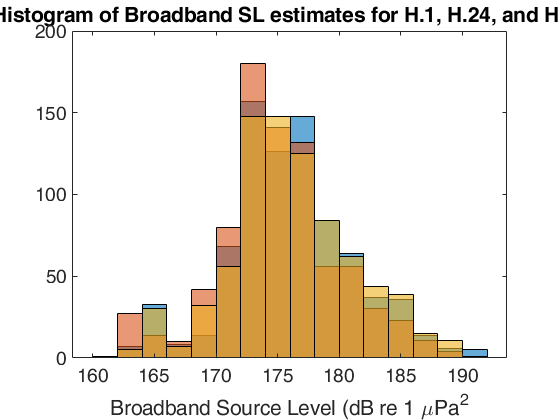

funPlotSPLHist(par, SL);

## Investigate lobing pattern

### Plot broadband lobing pattern

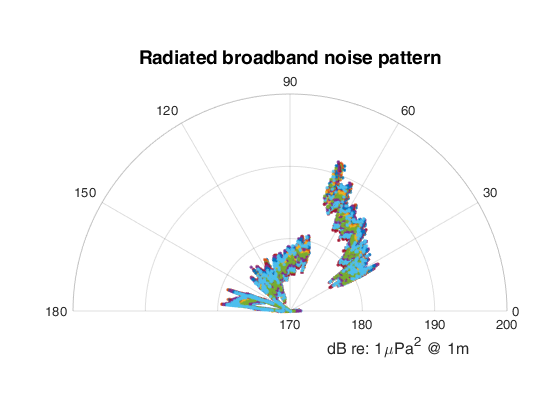

% figure
% polarpattern(SPL.aspect2,SPL.SL2,'TitleTop', 'Radiated noise pattern (dB)')
figure
polarscatter(SPL.rads(:,1)',SL.broadband(1,:),'.')
rlim(par.bbLim)
%[min(min(SL.broadband))-par.scale max(max(SL.broadband))]
thetalim([0 180])
title({'Radiated broadband noise pattern'},'FontSize',par.fontSize)
if NumRec == 48
    hold on
    for RecInd=2:par.scatInt:NumRec
        polarscatter(SPL.rads(:,RecInd)',SL.broadband(RecInd,:),'.')
    end
end
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa^2 @ 1m';

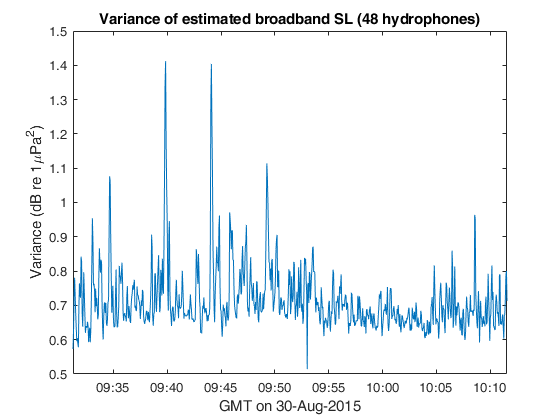


%plotBBsurface(zdata1, xdata1, ydata1)
figure
plot(SPL.timeVector,var(SL.broadband))
xlim([min(SPL.timeVector) max(SPL.timeVector)]);
datetick('x','keeplimits');
title('Variance of estimated broadband SL (48 hydrophones)')
xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);
ylabel('Variance (dB re 1\muPa^2)');

### Plot narrowband lobing pattern for C52, S180 and C75

Find max SL between 540 - 550 Hz and plot lobing pattern

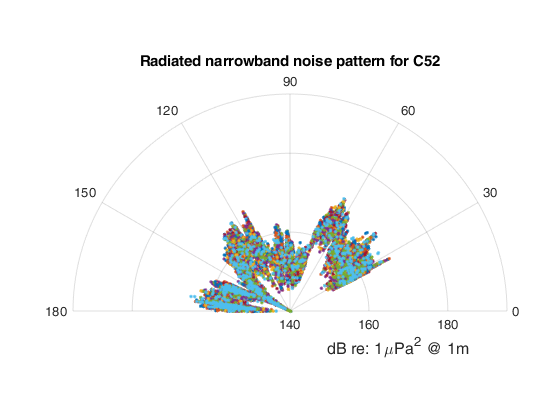

switch VOI
    case {'OcEnd-AAA1-30Aug','OcEnd-AAA2-30Aug'}
        int.C52 = 374:383;
        int.S180 = 501:512;
        int.C75 = 541:551;
    case {'OcEnd-AAA1-31Aug','OcEnd-AAA2-31Aug'}
        int.C52 = 365:371;
        int.S180 = 506:512;
        int.C75 = 528:536;
end
C52.max = zeros(NumSpec-2,NumRec);
C52.idx = zeros(NumSpec-2,NumRec);
S180.max = zeros(NumSpec-2,NumRec);
S180.idx = zeros(NumSpec-2,NumRec);
C75.max = zeros(NumSpec-2,NumRec);
C75.idx = zeros(NumSpec-2,NumRec);

for RecInd = 1:NumRec
    p = SL.ALL{RecInd,1}(:,int.C52);
    [C52.max(:,RecInd),C52.idx(:,RecInd)] = max(p,[],2);
    p = SL.ALL{RecInd,1}(:,int.S180);
    [S180.max(:,RecInd),S180.idx(:,RecInd)] = max(p,[],2);
    p = SL.ALL{RecInd,1}(:,int.C75);
    [C75.max(:,RecInd),C75.idx(:,RecInd)] = max(p,[],2);
end


figure
%subplot(1,3,1)
polarscatter(SPL.rads(:,1),C52.max(:,1),'.')
rlim(par.nbLim)
thetalim([0 180])
%rlim([min(min(C52.max))-par.scale max(max(C52.max))])
title({'Radiated narrowband noise pattern for C52'})
if NumRec == 48
    hold on
    for RecInd=2:par.scatInt:NumRec
        polarscatter(SPL.rads(:,RecInd)',C52.max(:,RecInd),'.')
    end
    %legend('H.1','H.12','H.24','H.36','H.48','Location','south')
end
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa^2 @ 1m';

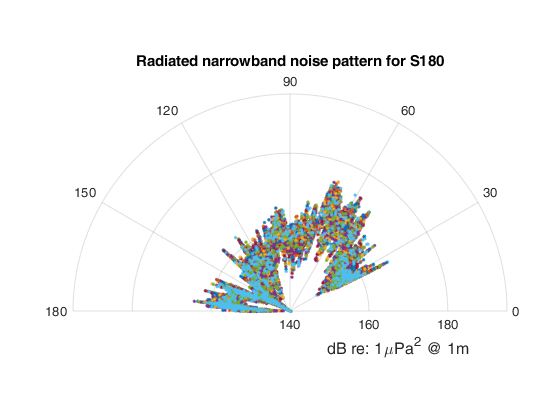


figure
%subplot(1,3,2)
polarscatter(SPL.rads(:,1),S180.max(:,1),'.')
rlim(par.nbLim)
thetalim([0 180])
%rlim([min(min(S180.max))-par.scale max(max(S180.max))])
title({'Radiated narrowband noise pattern for S180'})
if NumRec == 48
    hold on
    for RecInd=2:par.scatInt:NumRec
        polarscatter(SPL.rads(:,RecInd)',S180.max(:,RecInd),'.')
    end
    %legend('H.1','H.12','H.24','H.36','H.48','Location','south')
end
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa^2 @ 1m';

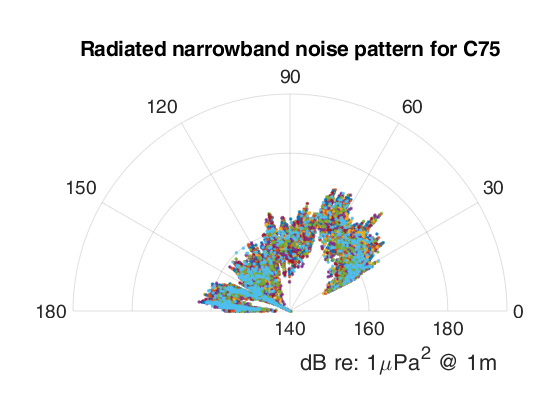


figure
%subplot(1,3,3)
polarscatter(SPL.rads(:,1),C75.max(:,1),'.')
rlim(par.nbLim)
thetalim([0 180])
%rlim([min(min(C75.max))-par.scale max(max(C75.max))])
title({'Radiated narrowband noise pattern for C75'})
if NumRec == 48
    hold on
    for RecInd=2:par.scatInt:NumRec
        polarscatter(SPL.rads(:,RecInd)',C75.max(:,RecInd),'.')
    end
    %legend('H.1','H.12','H.24','H.36','H.48','Location','south')
end
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa^2 @ 1m';
ax.FontSize = par.fontSize;


%tightenUp;


## Junk

### Plot ship aspects over track

% switch plotAspects
%     case 'no'
%     case 'yes'
%         figure
%         plot(SPL.timeVector,SPL.R2(:,RefRecInd,2))
%         hold on
%         plot(SPL.timeVector,SPL.R1(:,RefRecInd,2))
%         plot(SPL.timeVector,SPL.aspect2(:,RefRecInd))
%         plot(SPL.timeVector,SPL.aspect1(:,RefRecInd))
%         plot(SPL.timeVector,alpha(RefRecInd,:,1)')
%         plot(SPL.timeVector,alpha(RefRecInd,:,2)')
%         title({'Ship-array angle vs ship aspect \alpha (direct and inferred)'})
%         legend('Ship-AAA2','Ship-AAA1','\alpha_d AAA2','\alpha_d AAA1',...
%             '\alpha_i AAA2','\alpha_i AAA1')
% end